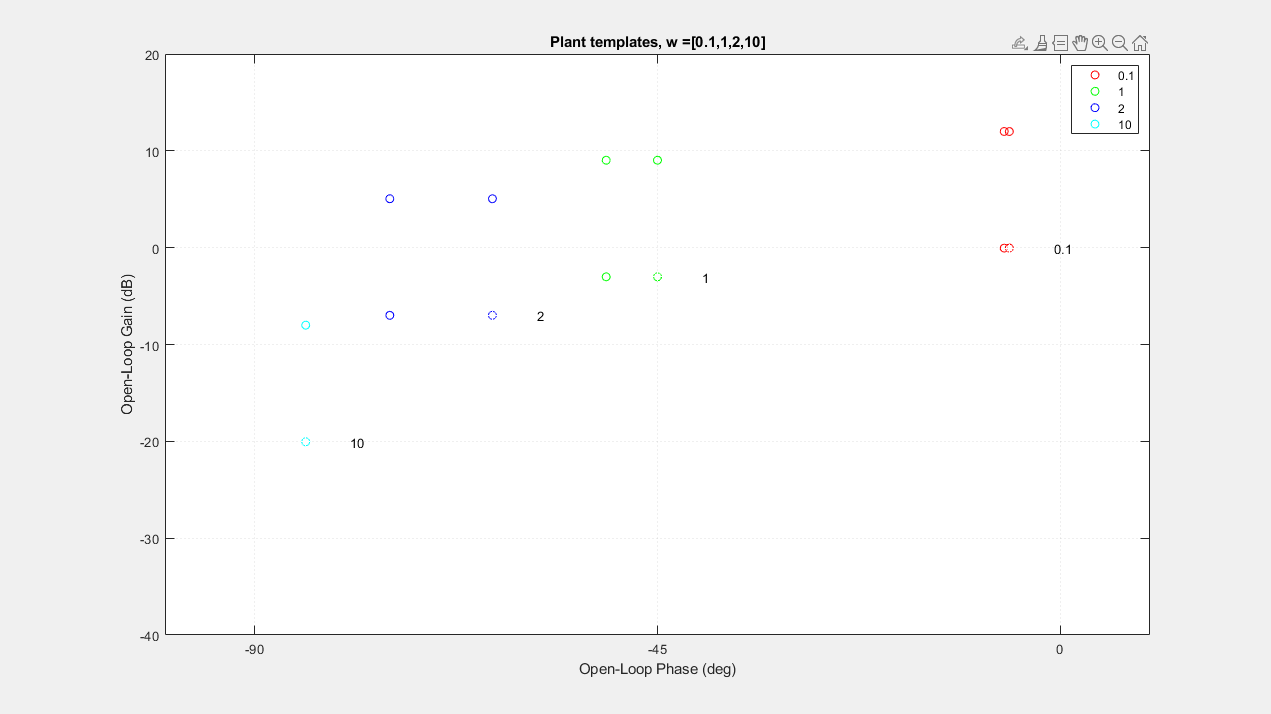

s = tf('s');

[kk,TT]=ndgrid([1,4],[0,0.1]); % define parameter grid

kk=kk(:); TT=TT(:); % make them column vectors
for i=1:length(kk) % define array of SISO plants
 P(1,1,i)=kk(i)*exp(-s*TT(i))/(s+1);
end

figure % Plot the templates
plottmpl([0.1,1,2,10],P)
title('Plant templates, w =[0.1,1,2,10]')
axis([-100,10,-40,20])

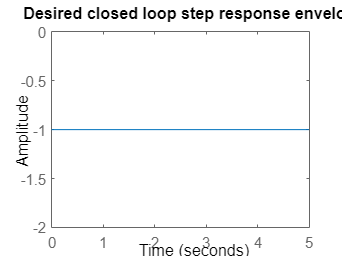


%Specifications
Tups=1.1/((s/3)^2+s/3+1); % upper bound
Tlos=0.9/((s/4+1)*((s/2)^2+2*s/2+1)); % lower bound
figure % Desired Step response
step(Tups, Tlos,5)
title('Desired closed loop step response envelope')


w=[0.1,1,2,10]; % define frequency points
% plottmpl(w,P,4) % draws the plant templates

ws = 10.^([-20,3,3,3]/20);

bnd=sisobnds(2,w,ws,P/(1+P)/s); % Calculate the nominal bounds from the specs
% plotbnds(bnd);           % Plot

% lpshape(w,bnd,P(1,1,1)/(1+P(1,1,1))/s) % Perform design